syms x y

disp(-laplacian(1/5*(sin(x)*sin(2*y))) == sin(x)*sin(2*y))

$$\sin\left(2\,y\right)\,\sin\left(x\right)=\sin\left(2\,y\right)\,\sin\left(x\right)$$

m = 3; h = 1;
I = eye(m);
e = ones(m,1);
T = spdiags([e -4*e e],[-1 0 1],m,m);
S = spdiags([e e],[-1 1],m,m);
A = (kron(I,T) + kron(S,I))/h^2;
full(A)

ans =     -4     1     0     1     0     0     0     0     0
     1    -4     1     0     1     0     0     0     0
     0     1    -4     0     0     1     0     0     0
     1     0     0    -4     1     0     1     0     0
     0     1     0     1    -4     1     0     1     0
     0     0     1     0     1    -4     0     0     1
     0     0     0     1     0     0    -4     1     0
     0     0     0     0     1     0     1    -4     1
     0     0     0     0     0     1     0     1    -4




D2 = spdiags([e -2*e e],[-1 0 1],m,m);
AD = (kron(I,D2) + kron(D2,I))/h^2;
full(AD)

ans =     -4     1     0     1     0     0     0     0     0
     1    -4     1     0     1     0     0     0     0
     0     1    -4     0     0     1     0     0     0
     1     0     0    -4     1     0     1     0     0
     0     1     0     1    -4     1     0     1     0
     0     0     1     0     1    -4     0     0     1
     0     0     0     1     0     0    -4     1     0
     0     0     0     0     1     0     1    -4     1
     0     0     0     0     0     1     0     1    -4



norm(A-AD,'inf')

ans = 0



N = 100;
m = N;
e = ones(N,1);

I = eye(m);
e = ones(m,1);
T = spdiags([e -4*e e],[-1 0 1],m,m);
S = spdiags([e e],[-1 1],m,m);
A = (kron(I,T) + kron(S,I));
%A = spdiags([e,e,-4*e,e,e],-2:2,N,N);
h = pi/(N+1);
Y = sin(2*(h:h:pi-h));
X = sin(1*(h:h:pi-h));


[X,Y] =meshgrid(X,Y);

U_true = 1/5 * X.*Y;

Fij = X.*Y;
Fij = reshape(Fij,N^2,1);
U = -h^2 *(A\Fij); 
U = reshape(U,N,N);

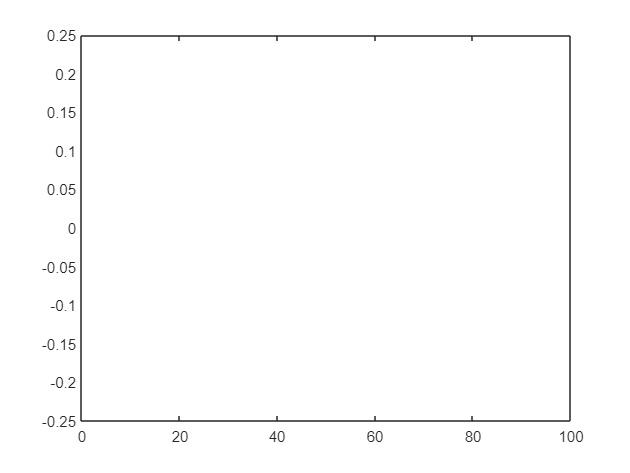

plot(U(:,N/2)), hold on
plot(U_true(:,N/2))
hold off

norm(U-U_true,'inf')

ans = 0.0035

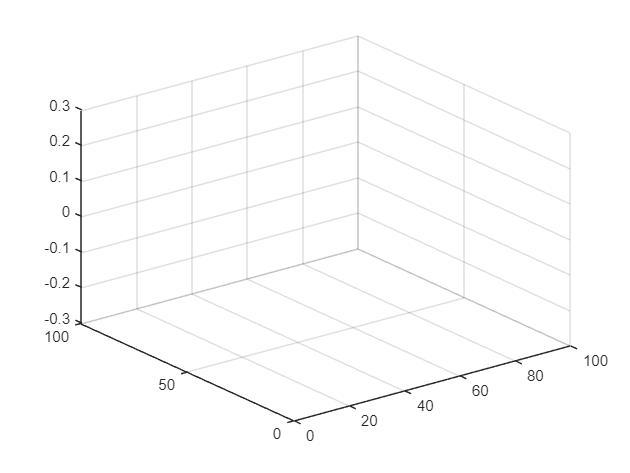

surf(U), hold on
surf(U_true)
hold off

function res = fun(x,y)
    res = sin(x)* sin(2*y);
end
